Immagini come nuvole di punti

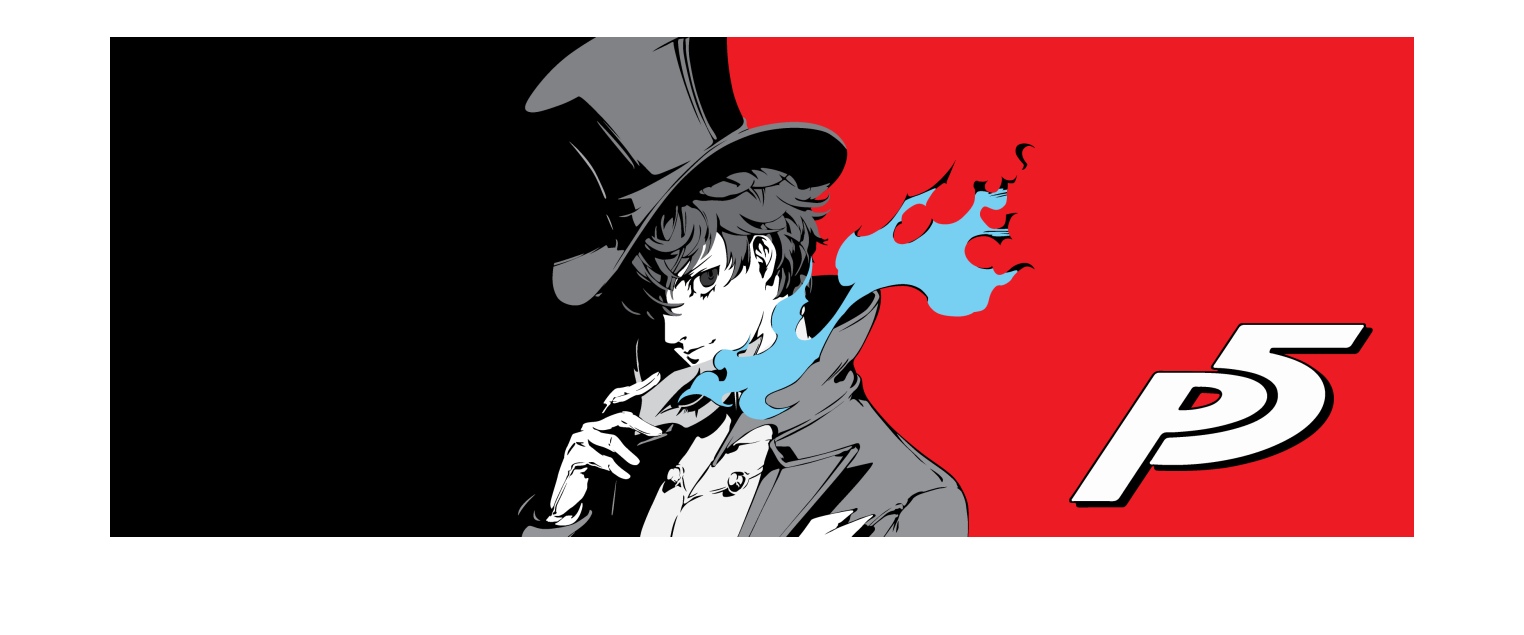

I = imread('./p5.png');
figure, imshow(I)

Costruisco le coordinate

r = I(:,:,1);
r = r(:);
g = I(:,:,2);
g = g(:);
b = I(:,:,3);
b = b(:);
rgb = [r, g, b];

Visualizzo come una nuvola di punti

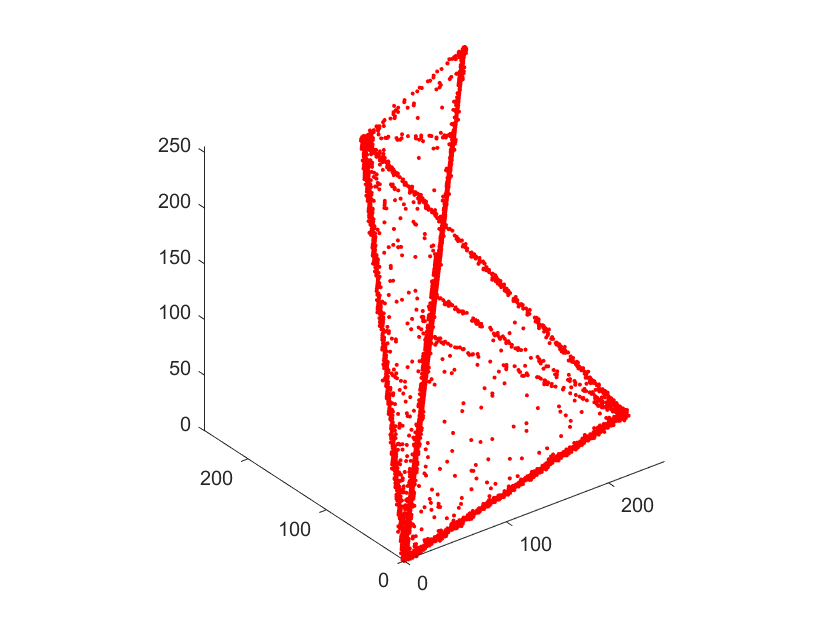

figure, plot3(r,g,b,'r.')
axis equal

Visualizzazione con i colori

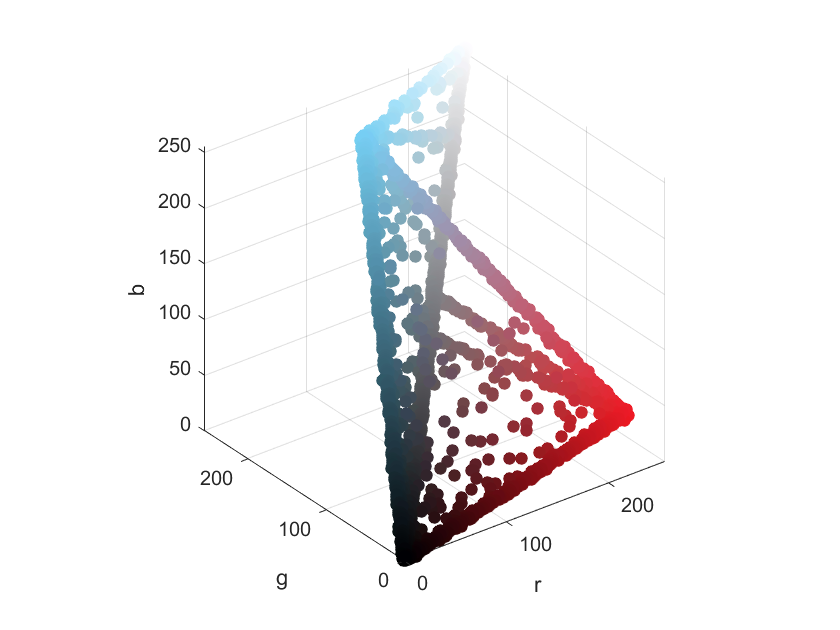

figure
scatter3(r,g,b,40,double(rgb)./255,'fill')
axis equal
xlabel('r')
ylabel('g')
zlabel('b')

Produco l'istogramma 3d

n = 100;
[~,c,s] = kmeans(double(rgb), n);

Visualizzo l'istogramma

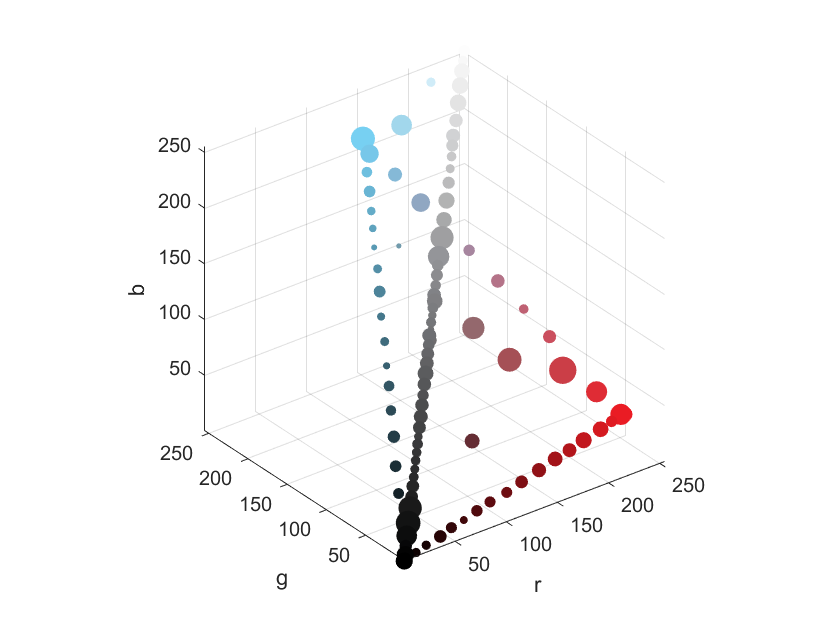

figure
scatter3(c(:,1),c(:,2),c(:,3),s*1e-2,c./255,'fill')
axis equal
xlabel('r')
ylabel('g')
zlabel('b')